cd G:\Masters\Thesis\Data\data

## Importing data

% Get current directory
current_path = pwd;

% Get all files in the directory
file_names = dir(current_path);

% Initialize array to store CSV files
csv_files = {};

% Loop through the files
for i = 1:numel(file_names)
    % Check if it's a file and has .csv extension
    [~, ~, ext] = fileparts(file_names(i).name);
    if ~file_names(i).isdir && strcmp(ext, '.csv')
        % Append to csv_files array
        csv_files = [csv_files, file_names(i).name];
    end
end

% Display the list of CSV files
disp(csv_files);

  Column 1

    {'test78x.csv'}

  Column 2

    {'test78y.csv'}

  Column 3

    {'test89x.csv'}

  Column 4

    {'test89y.csv'}

  Column 5

    {'test910x.csv'}

  Column 6

    {'test910y.csv'}

  Column 7

    {'testT78x.csv'}

  Column 8

    {'testT78y.csv'}

  Column 9

    {'testT89x.csv'}

  Column 10

    {'testT89y.csv'}




% Initialize cell array to store dataframes
test_df = {};

% Loop through CSV files
for i = 1:numel(csv_files)
    % Read CSV file
    df = readtable(csv_files{i});
    % Append to test_df cell array
    test_df = vertcat(test_df, df);
end

% Display the number of rows
fprintf('There are total number of %d rows\n', size(test_df, 1));

There are total number of 24 rows



% Display the first 10 rows
disp(head(test_df, 10));

    Var1       date         time                kks                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                 

## Extracting data  from tabels

% Initialize matrix to store all data
num_rows = height(test_df);
all_data = zeros(num_rows, 25000);

% Loop through each row of the table
for i = 1:num_rows
    % Extract data from the 'data' column and evaluate it
    data_str = test_df.data{i};
    data = eval(data_str);
    
    % Reshape and detrend the data
    data = reshape(data, 1, []);
    data = detrend(data);
    
    % Store the detrended data in the matrix
    all_data(i, :) = data;
end


## Plotting signals

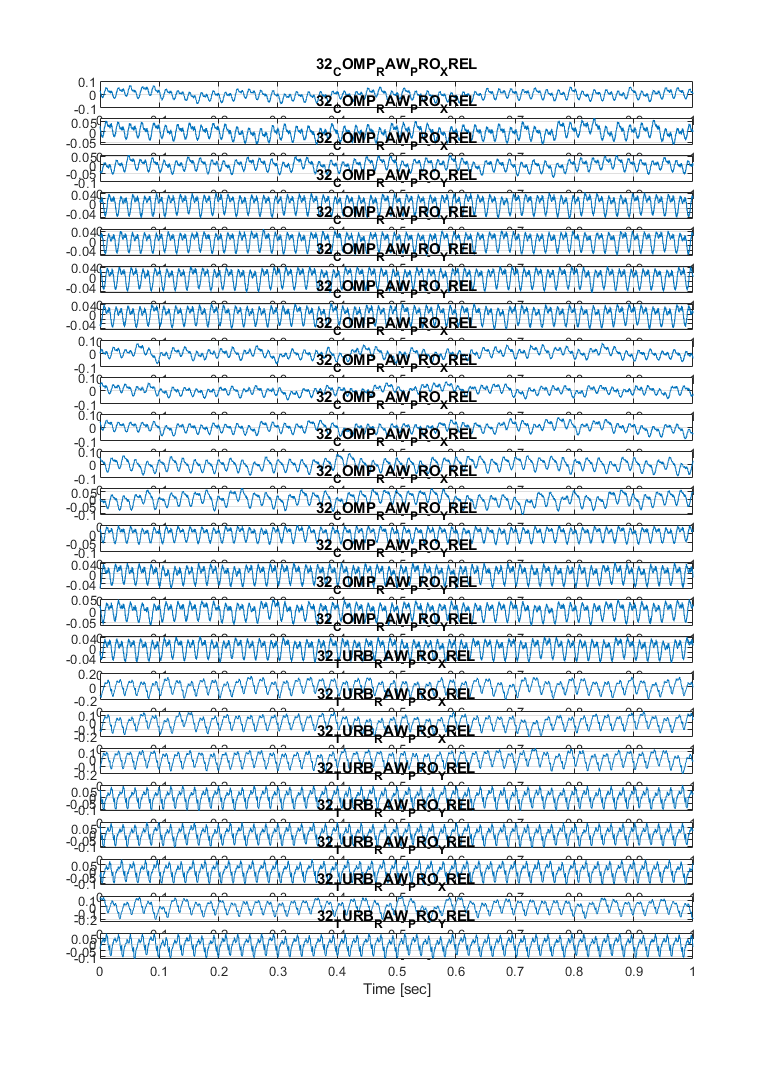

hight = size(test_df, 1); % Get the number of rows in the table
H = hight * 3; % Calculate the height of the figure

% Create a figure with specified height
figure('Position', [100, 100, 800, H]);

% Generate x-axis values
x_axis = linspace(0, 1, 25000);

% Plotting signals
for i = 1:hight
    subplot(hight, 1, i);
    plot(x_axis, all_data(i, :));
    xlabel('Time [sec]');
    title(test_df.kks{i});
    grid on;
end

% Adjust subplot spacing
set(gcf, 'PaperUnits', 'inches', 'PaperPosition', [0 0 10 H]);
set(gcf, 'Units', 'normalized', 'Position', [0 0 2 5]);

set(gcf, 'Units', 'normalized', 'OuterPosition', [0 0 2 5]);

## Hilbert-Huang Spectrum

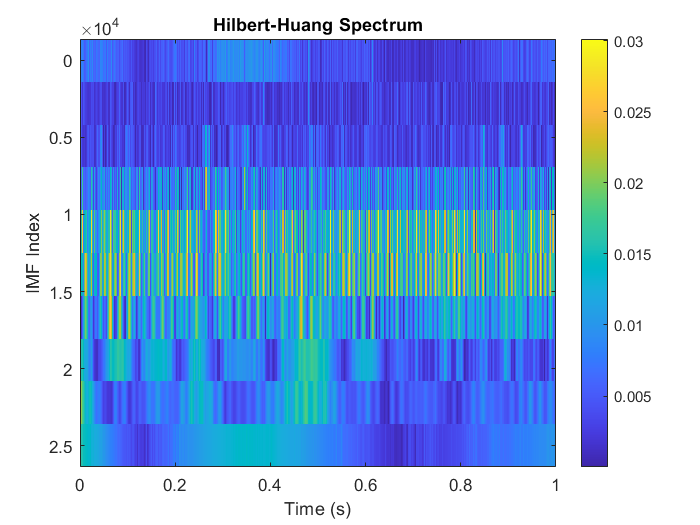

% Sample signal (replace with your own signal)
Fs = 25000; % Sampling frequency
t = linspace(0,1,Fs); % Time vector
x = all_data(1,:); % Example signal

% Empirical Mode Decomposition (EMD)
imf = emd(x);
imf_size = size(imf);

% Hilbert Transform
hilbert_spectrum = zeros(length(t), imf_size(2));
for i = 1:length(imf)
    analytic_signal = hilbert(imf(i,:));
    hilbert_spectrum(i,:) = abs(analytic_signal);
end

% Plotting
figure;
imagesc(t, 1:length(imf), hilbert_spectrum');
xlabel('Time (s)');
ylabel('IMF Index');
title('Hilbert-Huang Spectrum');
colorbar;

## Pspectrum

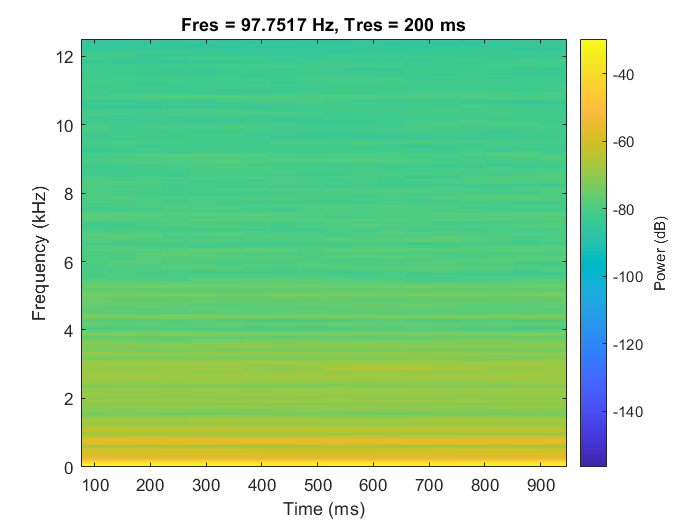

pspectrum(x,25000,'spectrogram','TimeResolution',0.2)